# INTERPOLACJA

## Wykorzystanie interpolacji do analizy sygnałów - idea współczynników korelacji

Do tej pory poznaliśmy głównie bazę wielomianową. Wielomiany nie są zbyt użytecznymi funkcjami w tym zastosowaniu, ponieważ nie oddają dobrze właściwości rzeczywistych sygnałów (jaki widzieliśmy takie interpolacje niewiele nam mówią). Jednak idea wykorzystania interpolacji do analizy sygnału może zostać przedstawiona na tym przykładzie o ile funkcją oryginalną będzie wielomian. 

Poniższy kod wykonuje interpolację wielomianową i wyświetla współczynniki tej interpolacji. Funkcja analizująca przyjmuje współrzędne x punktów wejściowych oraz długość bazy wielomianowej.

**UWAGA!** W przypadku podania zbyt długiej bazy zostanie zastosowany padding - czyli dopełnienie brakujących punktów zerami na końcu szeregu. W przypadku zastosowania analizy za pomocą wielomianów nie jest to w żaden sposób pomocne, ale chodzi o oswojenie się z tą techniką.

**ĆWICZENIE 1:**

Korzystając z poniższego kodu spróbuj zanalizować różne rodzaje wielomianów przy różnych konfiguracjach danych wejściowych i długości bazy. Zobacz kiedy uzyskujesz sensowne wyniki, które dają użyteczne informacje a kiedy nie. 

Wypróbuj funkcje oryginalne które są wielomianami i które nie są.

Spróbuj ustawić długość bazy na większą od ilości punktów i na mniejszą.

Spróbuj ustawić długość bazy na taką, żeby nie było największej składowej wielomianu oryginalnego.

Współczynnik p1 = -1.08e+01
Współczynnik p2 = 1.63e+02
Współczynnik p3 = -9.19e+02
Współczynnik p4 = 2.43e+03
Współczynnik p5 = -2.96e+03
Współczynnik p6 = 1.30e+03


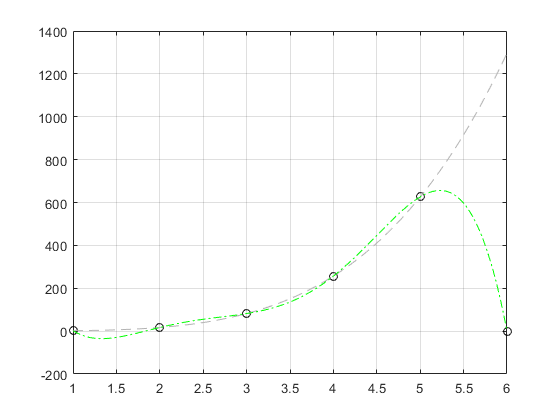

%Funkcja oryginalna
f=@(x) x.^4+1;

%Położenia węzłów
xw = [1:1:5];

%Ilość funkcji z bazy
noOfFunctions = 6;

doStuff(xw, noOfFunctions, f);

**WYKROZYSTYWANE FUNKCJE**

function doStuff(xw, noOfFunctions, fun)

%dodawanie paddingu
if(noOfFunctions>numel(xw))
    yw_plus=zeros(1, noOfFunctions-numel(xw));
    h=mean(diff(xw));
    yw = fun(xw);
    xw=[xw [max(xw)+h:h:max(xw)+(noOfFunctions-numel(xw))]];
    yw = [yw yw_plus];
end

%jezeli za dużo punktów
if(noOfFunctions<numel(xw))
    xw=xw(1:noOfFunctions);
    yw = fun(xw);
end

if(~exist('yw'))
    yw = fun(xw);
end


plot(xw,yw,'ok');

xx=[min(xw):0.01:max(xw)];
yy=fun(xx);

hold on;
plot(xx,yy,'k--', 'Color',[0.7 0.7 0.7]);
grid on;set(gcf,'Color','white');

wsp=polyfit(xw,yw,noOfFunctions-1);
for i=1:1:noOfFunctions
    fprintf('Współczynnik p%d = %0.2e\n',i,wsp(i));
end

plot(xx,polyval(wsp,xx),'g-.'); hold off;
end